# 第11章 图像识别

## SVM（支持向量机)

【例11-2】 利用MATLAB自带的Fisheriris(鸢尾花)数据集，来识别花的种类

注：书上使用的函数已经被移除，现已修改为R2020a可以运行的版本

### SVM训练

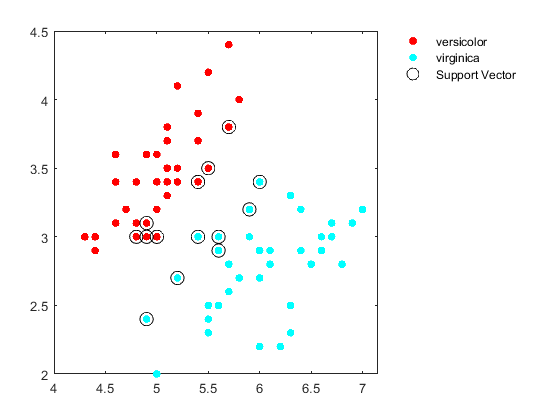

load fisheriris.mat
%为方便实验，只取第1，2列特征
meas =meas(:,1:2);
%分别选取Setosa类和Versicolor类前40组作为训练数据，后10组作为测试数据
%分别选取Setosa类和Versicolor类前40组作为训练数据,后10组作为测试数据
trainData=[meas(1:40,:);meas(51:90,:)];
trainType = [species(1:40);species(51:90)];
%使用训练数据,对SVM模型进行训练
%R2021中svmtrain已经被删除，可以使用fitcsvm
SVMModel = fitcsvm( trainData, trainType);
sv = SVMModel.SupportVectors;
figure();
gscatter(trainData(:,1),trainData(:,2),trainType)
hold on
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
legend('versicolor','virginica','Support Vector','location','bestoutside')
hold off

### SVM使用测试数据,得到识别结果

testData= [meas(41:50,:);meas(91:100,: )];
trueType = [species(41:50);species(91:100)];
label = predict(SVMModel,testData);
%正确的识别结果为trueType ,实验测试的识别结果为label
%计算分类精度
tureNum =sum(strcmp(label, trueType));
fprintf( '识别正确率为:%f\n' , tureNum/length(testData));

识别正确率为:0.950000


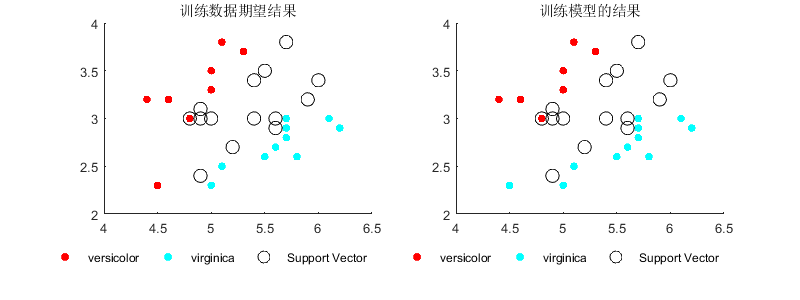

figure('Position',[0,0,800,300])
subplot(1,2,1);hold on
gscatter(testData(:,1),testData(:,2),trueType)
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
hold off;title("训练数据期望结果")
legend('versicolor','virginica','Support Vector','Orientation',"horizontal",'Location',"bestoutside")
subplot(1,2,2);hold on
gscatter(testData(:,1),testData(:,2),label)
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)
hold off;title("训练模型的结果")
legend('versicolor','virginica','Support Vector','Orientation',"horizontal",'Location',"bestoutside")